#### 1. Função de Transferência do sistema

a = 14.97;
s = tf('s');
Kp = 750;
Ts = 0.008; % Período de amostragem (Ts = 8ms)
Gp = a * Kp /(s+a);
Gp_zpk = zpk(Gp)

Gp_zpk =
 
    11228
  ---------
  (s+14.97)
 
Continuous-time zero/pole/gain model.
Model Properties


#### 2. Modelo em espaço de estado


$$\dot{\mathbf{x}}(t) = \mathbf{A}\mathbf{x}(t) + \mathbf{B}\mathbf{u}(t) \\
\mathbf{y}(t) = \mathbf{C}\mathbf{x}(t) + \mathbf{D}\mathbf{u}(t)
$$


[num, den] = tfdata(Gp, 'v'); 
[Ac, Bc, Cc, Dc] = tf2ss(num, den);


#### 3. Sistem em espaço de estados

sys = ss(Ac, Bc, Cc, Dc) % Sistema tempo contínuo

sys =
 
  A = 
           x1
   x1  -14.97
 
  B = 
       u1
   x1   1
 
  C = 
              x1
   y1  1.123e+04
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.
Model Properties


#### 3.1 Resposta ao degrau

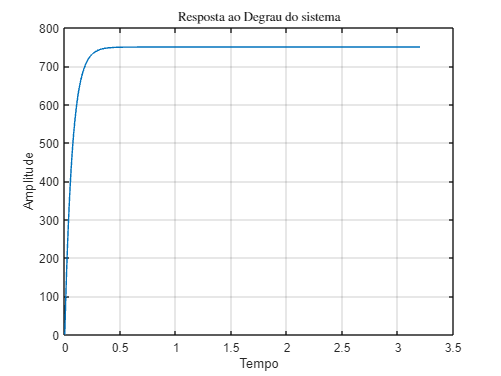

t = 0:400;
t = t*Ts;

[yp, tp] = step(sys, t);

figure;
plot(tp, yp);
title('Resposta ao Degrau do sistema', 'Interpreter', 'latex');
ylabel('Amplitude');
xlabel('Tempo');
grid on;

#### 4.  Projetando o Controlador

**4.1 Avaliando Controlabilidade e Observabilidade**

% Controlabilidade

Sz = Bd;

if length(Sz)==1
    if Sz~=0
        fprintf("É controlável.");
    else
        fprintf("Não é controlável.");
    end
else
    if det(Sz)~=0
        fprintf("É controlável.");
    else
        fprintf("Não é controlável.");
    end
end

É controlável.


% Convertendo para FCC

Q1_c = 1 * Sz^(-1);

Q_c = Q1_c;

Ax_fcc = Q_c*Ad*Q_c^(-1)

Ax_fcc = 2.0666e-10

Bx_fcc = Q_c*Bd

Bx_fcc = 1

Cx_fcc = Cd*Q_c^(-1)

Cx_fcc = 750.0000


Sx = Bx_fcc;

P_c = Sz*Sx^(-1);

% Observabilidade

Vz = Cd;

if length(Vz)==1
    if Vz~=0
        fprintf("É observável.");
    else
        fprintf("Não é observável.");
    end
else
    if det(Vz)~=0
        fprintf("É observável.");
    else
        fprintf("Não é observável.");
    end
end

É observável.


% Convertendo para FCO

Q1_o = Cd^(-1) * 1;

Q_1_o = Q1_o;

Q_o = Q_1_o^(-1);

Ax_fco = Q_o*Ad*Q_1_o

Ax_fco = 2.0666e-10

Bx_fco = Q_o*Bd

Bx_fco = 750.0000

Cx_fco = 1

Cx_fco = 1


Vx = Cx_fco;

P_o = Vz^(-1)*Vx;

**4.2 Definindo Especificações de Desempenho **

% Polos desejados
cf = 700;
cmax = 800;

% Ultrapassagem percentual.
Up = ((cmax-cf)/cf) * 100 

Up = 14.2857

% Tempo de acomodação.
Ts = 1.5 ;

qsi = (-log(Up/100))/(sqrt(pi^2+log(Up/100)^2));

% Calcula o fator de amortecimento
% requerido.

wn = 4/(qsi*Ts); % Calcula a frequência natural
% requerida.

[numd,dend] = ord2(wn,qsi); % Produz um sistema de
% segunda ordem que atende aos
% requisitos de resposta transitória.

r = roots(dend); % Usa o denominador para
% especificar os polos dominantes.

polos = [r(1) r(2)] % Especifica a posição de todos

polos =   -2.6667 + 4.3052i  -2.6667 - 4.3052i


% os polos.

eq_caracteristica_desejada = poly(polos);

fprintf('Equação característica desejada:\n');

Equação característica desejada:


fprintf('s^2 + %.2fs + %.2f\n', ...
    eq_caracteristica_desejada(2), ...
    eq_caracteristica_desejada(3));

s^2 + 5.33s + 25.65


**4.3 Adicionando Ação Integral**

% Construção do sistema aumentado
A_hat = [Ac     zeros(size(Ac,1),1);
         -Cc     0]

A_hat = 1.0e+04 *

   -0.0015         0
   -1.1227         0



B_hat = [Bc;
         0]

B_hat =      1
     0



C_hat = [Cc 0]

C_hat = 1.0e+04 *

    1.1227         0



% Polos desejados (reutilizados ou altere para adicionar um terceiro)
% Adicionando um polo extra mais à esquerda para o integrador


% Projeto do ganho com realimentação de estados aumentados
K_hat = acker(A_hat, B_hat, polos);

% Extração dos ganhos K e Ki
K  = K_hat(1:end-1)

K = -9.6367

Ki = -K_hat(end)

Ki = 0.0023


% Sistema em malha fechada com integrador
A_hat_cl = [Ac - Bc*K, Bc*Ki;
            -Cc      ,  0];

B_hat_cl = [0; 1];  % Entrada de referência
C_hat_cl = [Cc 0];
D_hat_cl = 0;

sys_ss = ss(A_hat_cl, B_hat_cl, C_hat_cl, D_hat_cl);
sys_tf = tf(sys_ss);  % Converte espaço de estados para FT

[y, tOut] = step(sys_tf, t);

zpk(sys_tf)           % Exibe zeros, polos e ganho

ans =
 
          25.646
  ----------------------
  (s^2 + 5.333s + 25.65)
 
Continuous-time zero/pole/gain model.
Model Properties


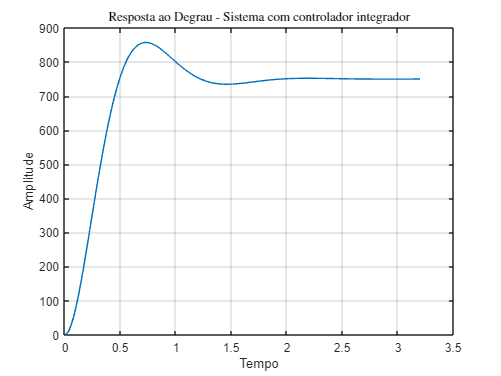


% Plotagem dos estados
figure;
plot(tOut, y*Kp);
title('Resposta ao Degrau - Sistema com controlador integrador', 'Interpreter', 'latex');
ylabel('Amplitude');
xlabel('Tempo');
grid on;

**4.4  Análise das EDS**

info = stepinfo(y, tOut);

% Tempo de acomodação a 2%
Ts = info.SettlingTime;
Tr = info.RiseTime;
Tp= info.PeakTime;
UP= info.Overshoot;
fprintf('Tempo de subida : %.4f ms\n', Tr);

Tempo de subida : 0.3338 ms


fprintf('Tempo de acomodação: %.4f ms\n', Ts);

Tempo de acomodação: 1.4896 ms


fprintf('Tempo de pico : %.4f ms\n', Tp);

Tempo de pico : 0.7280 ms


fprintf('Ultrapassagem percentual : %.4f ms\n', UP);

Ultrapassagem percentual : 14.3061 ms


### **5. Projetando o Observador**

#### **5.1 Equação caracteristica desejada do observador**

**(Ts 10x menor do que o do controlar)**

Ts_obs = (Ts / 10);
wn_obs = 4/(qsi*Ts_obs); % Calcula a frequência natural

polo_o = qsi*wn_obs

polo_o = 26.8521

#### **5.2 Ganho do observador**

L = -place(Ac', Cc', polo_o)'

L = 0.0037

#### **5.3 Simulação do observador**


$$ \dot{x}(t) = A x(t) + Bu(t)\\
 \dot{\hat{x}}(t) = (A-LC) \hat{x}(t) + LC x(t) + Bu(t)$$



$$    \dot{\hat{x}} = A_o \hat{x} + B_o z \\
    y_o = C_o \hat{x}
$$
  


$$A_o =A-\mathrm{LC}$$
 
$$;B_o =\left\lbrack \begin{array}{cc}
B & L
\end{array}\right\rbrack$$

$$;C_o =I_n$$

$$;z=\left\lbrack \begin{array}{c}
u\\
y
\end{array}\right\rbrack$$


o vetor z que consiste na entrada e na saída do sistema é a entrada do observador

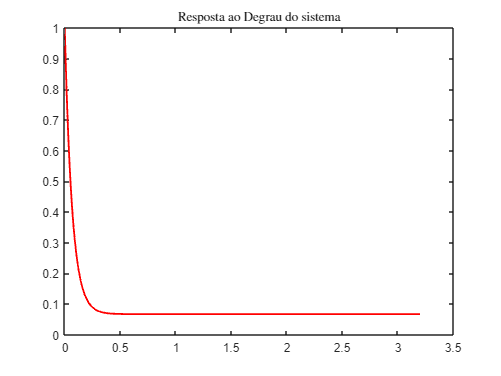

input = ones(size(t));
x0true = [1];
[yTrue, timeTrue, xTrue] = lsim(sys,  input, t, x0true) ;

figure;
plot(timeTrue, xTrue(:,1), 'r', 'LineWidth', 1.5, 'DisplayName', '$y(t)$')
title('Resposta ao Degrau do sistema', 'Interpreter', 'latex');

% compute the closed-loop matrix 
Acl=Ac-L*Cc;
% check the closed -loop eigenvalues
polePlaced=eig(Acl);
abs(sort(polo_o)-sort(polePlaced));

Aobserver=Acl

Aobserver = -56.7921

Bobserver=[Bc L]

Bobserver =     1.0000    0.0037


Cobserver=eye(1,1)

Cobserver = 1

Dobserver=[]


Dobserver =

     []



sysObserver=ss(Aobserver,Bobserver,Cobserver,Dobserver)

sysObserver =
 
  A = 
           x1
   x1  -56.79
 
  B = 
             u1        u2
   x1         1  0.003725
 
  C = 
       x1
   y1   1
 
  D = 
       u1  u2
   y1   0   0
 
Continuous-time state-space model.
Model Properties


inputUY=[input;yTrue';]

inputUY = 1.0e+04 *

    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    1.1227    1.0045    0.8996    0.8065    0.7240    0.6507    0.5857    0.5281    0.4769    0.4316    0.3913    0.3556    0.3240    0.2959    0.2709    0.2488    0.2292    0.2118    0.1964    0.1827    0.1705    0.1597    0.1502    0.1417    0.1342    0.1275    0.1216    0.1163    0.1116    0.1075    0.1038    0.1006    0.0977    0.0951    0.0929    0.0908    0.0891    0.0875    0.0861    0.0848    0.0837    0.0827    0.0819    0.0811    0.0804    0.0798    0.0792    0.07

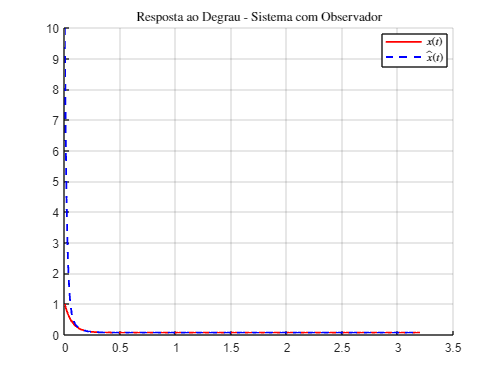

X0observer=[10];
[yObserver,timeObserver,xObserver] = lsim(sysObserver,inputUY,t,X0observer);

% here, we plot the observer state and the true state of the system 
figure;
hold on
plot(timeTrue,xTrue(:,1), 'r', 'LineWidth', 1.5, 'DisplayName', '$x(t)$')
plot(timeObserver,xObserver(:,1), 'b--', 'LineWidth', 1.5, 'DisplayName', '$\hat{x}(t)$')
title('Resposta ao Degrau - Sistema com Observador', 'Interpreter', 'latex');

legend('Interpreter', 'latex', 'Location', 'best');
grid on;
hold off;

#### 3. Discretização das equações de estado


$$\mathbf{x}[k+1] = \mathbf{A}_d \, \mathbf{x}[k] + \mathbf{B}_d \, \mathbf{u}[k] \\
\mathbf{y}[k] = \mathbf{C}_d \, \mathbf{x}[k]
$$


sysd = c2d(sys,Ts,'zoh')

sysd =
 
  A = 
              x1
   x1  2.067e-10
 
  B = 
           u1
   x1  0.0668
 
  C = 
              x1
   y1  1.123e+04
 
  D = 
       u1
   y1   0
 
Sample time: 1.4896 seconds
Discrete-time state-space model.
Model Properties
